DEEP LEARNING ASSIGNMENT 3

AVINASH MALLICK

19113015

CSE-7A

EXP: 4 Class problem with Multi Layer Perceptron

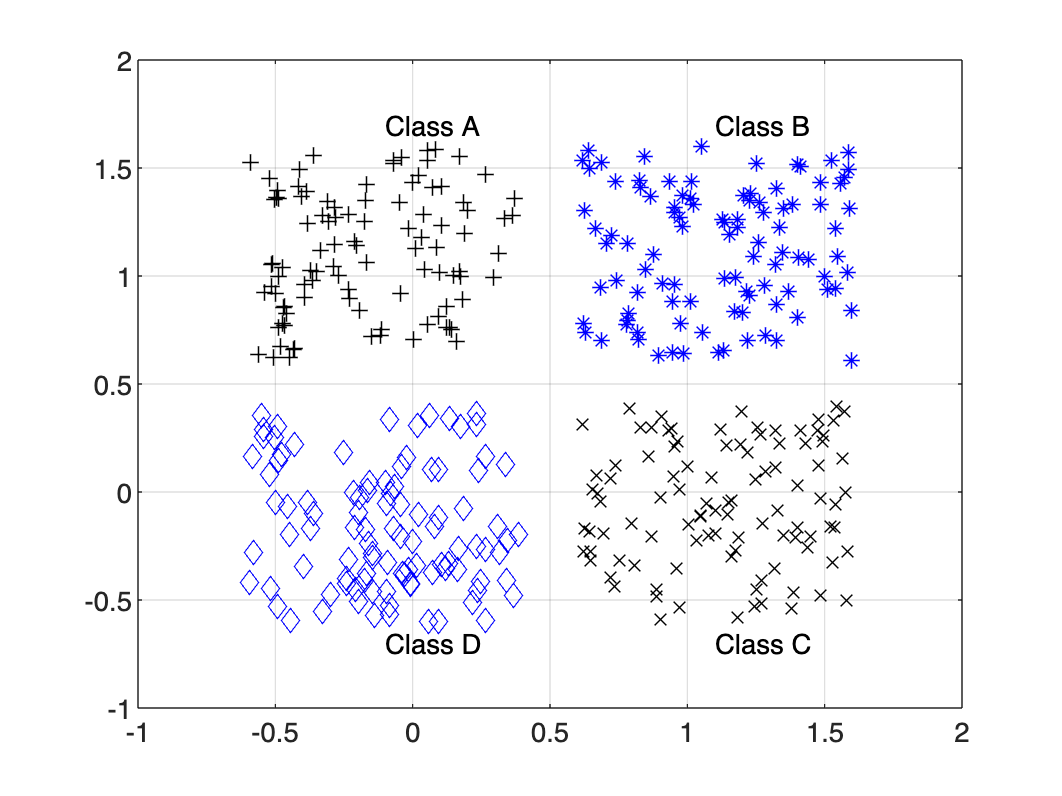

close all, clear all, clc, format compact

% number of samples of each class
K = 100;
% define 4 clusters of input data
q = .6; % offset of classes
A = [rand(1,K)-q; rand(1,K)+q];
B = [rand(1,K)+q; rand(1,K)+q];
C = [rand(1,K)+q; rand(1,K)-q];
D = [rand(1,K)-q; rand(1,K)-q];
% plot clusters
figure(1)
plot(A(1,:),A(2,:),'k+')
hold on
grid on
plot(B(1,:),B(2,:),'b*')
plot(C(1,:),C(2,:),'kx')
plot(D(1,:),D(2,:),'bd')
% text labels for clusters
text(.5-q,.5+2*q,'Class A')
text(.5+q,.5+2*q,'Class B')
text(.5+q,.5-2*q,'Class C')
text(.5-q,.5-2*q,'Class D')

% coding (+1/-1) of 4 separate classes
a = [-1 -1 -1 +1]';
b = [-1 -1 +1 -1]';
d = [-1 +1 -1 -1]';
c = [+1 -1 -1 -1]';

% define inputs (combine samples from all four classes)
P = [A B C D];
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B)) ...
     repmat(c,1,length(C)) repmat(d,1,length(D)) ];

% create a neural network
net = feedforwardnet([4 3]);

% train net
net.divideParam.trainRatio = 1; % training set [%]
net.divideParam.valRatio   = 0; % validation set [%]
net.divideParam.testRatio  = 0; % test set [%]

% train a neural network
[net,tr,Y,E] = train(net,P,T);

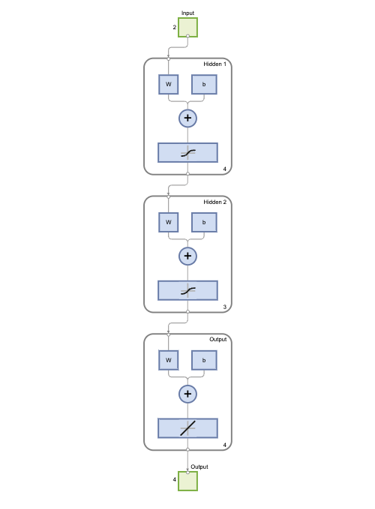

view(net)

% evaluate performance: decoding network response
[m,i] = max(T); % target class
[m,j] = max(Y); % predicted class
N = length(Y);  % number of all samples
k = 0;          % number of missclassified samples
if find(i-j),   % if there exist missclassified samples
  k = length(find(i-j)); % get a number of missclassified samples
end
fprintf('Correct classified samples: %.1f%% samples\n', 100*(N-k)/N)

Correct classified samples: 100.0% samples


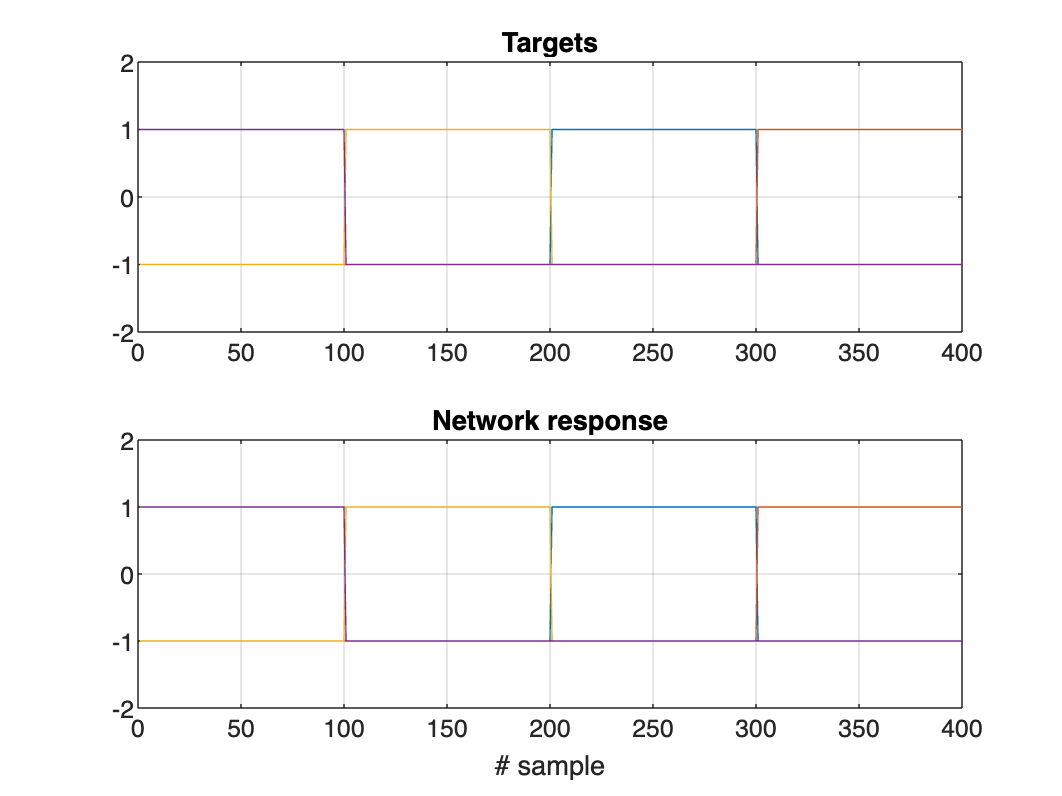


% plot network output
figure;
subplot(211)
plot(T')
title('Targets')
ylim([-2 2])
grid on
subplot(212)
plot(Y')
title('Network response')
xlabel('# sample')
ylim([-2 2])
grid on

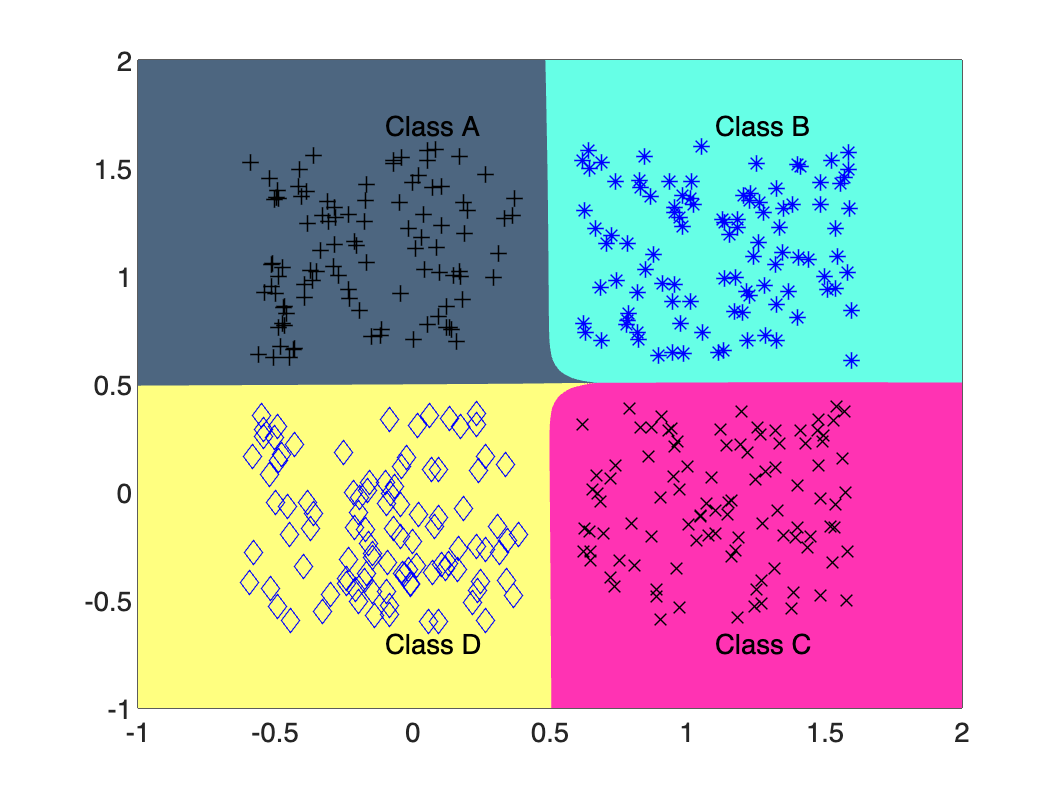

% generate a grid
span = -1:.01:2;
[P1,P2] = meshgrid(span,span);
pp = [P1(:) P2(:)]';

% simualte neural network on a grid
aa = net(pp);

% plot classification regions based on MAX activation
figure(1)
m = mesh(P1,P2,reshape(aa(1,:),length(span),length(span))-5);
set(m,'facecolor',[1 0.2 .7],'linestyle','none');
hold on
m = mesh(P1,P2,reshape(aa(2,:),length(span),length(span))-5);
set(m,'facecolor',[1 1.0 0.5],'linestyle','none');
m = mesh(P1,P2,reshape(aa(3,:),length(span),length(span))-5);
set(m,'facecolor',[.4 1.0 0.9],'linestyle','none');
m = mesh(P1,P2,reshape(aa(4,:),length(span),length(span))-5);
set(m,'facecolor',[.3 .4 0.5],'linestyle','none');
view(2)